clear
clc

Se va a importar la base de datos

% Se escoje la base de datos que se quiere analizar 
% data = importdata("sec1.mat");
% data = importdata("sec8.mat"); 
data = importdata("sec9.mat");

Numero de puntos por anillo

puntos = 20;   

Definición de variables para la construcción de la Matriz de puntos de control

Matriz_1 = [];
s1 = 1:4:80;
s2 = 2:4:80;
s3 = 3:4:80;
s4 = 4:4:80;
Matriz_puntos_control = [];                              

Visualización del data set

for i = 0:6
    % Puntos de control
    frac = data((i*puntos)+1:puntos*(i+1),1:3);
    plot3(frac(:,1),frac(:,2),frac(:,3),'--sb',...
        'MarkerEdgeColor','r',...
        'MarkerFaceColor',[1 .6 .6])
    hold on, grid on,
    title('Plot of the fracture','FontSize',13)
    xlabel('x axis')
    ylabel('y axis')
    zlabel('z axis')
    
    %Definicion de variables
    s = size(frac);
    n1 = s(1);
    
    %Puntos de Bézier
    for i2 = 1:n1
        k2 = i2+1;
        j2 = i2+2;
        q2 = i2+3;
        e1 = s1(i2);
        e2 = s2(i2);
        e3 = s3(i2);
        e4 = s4(i2);

        if k2 > n1
            k2 = i2-(n1-1);
        end
        if j2 > n1
            j2 = i2-(n1-2);
        end

        if q2 > n1
            q2 = i2-(n1-3);
        end


        for i3 = 1:3
            % En cada ciclo se guarda en la matriz M cada una de las coordenadas:
            %          primer ciclo: coordenadas x
            %          segundo ciclo: coordenadas y
            %          tercer ciclo: coordenadas z


            n2 = 3;


            p0 = frac(k2,i3);
            p1 = (frac(j2,i3)/2) - (frac(i2,i3)/2);
            p2 = frac(i2,i3) - (5*frac(k2,i3)/2) + (2*frac(j2,i3)) - (frac(q2,i3)/2);
            p3 = (3*frac(k2,i3)/2) - (frac(i2,i3)/2) - (3*frac(j2,i3)/2) + (frac(q2,i3)/2);


            % Componentes bin
            b00 = p0/nchoosek(n2,0);
            b10 = p1/nchoosek(n2,1);
            b20 = p2/nchoosek(n2,2);
            b30 = p3/nchoosek(n2,3);

            b01 = b10 + b00;
            b11 = b20 + b10;
            b21 = b30 + b20;

            b02 = b11 + b01;
            b12 = b21 + b11;

            b03 = b02 + b12;

            Matriz_1(e1,i3) = b00;
            Matriz_1(e2,i3) = b01;
            Matriz_1(e3,i3) = b02;
            Matriz_1(e4,i3) = b03;

        end


    end
    
    Matriz_puntos_control(:,:,i+1) = Matriz_1;
end 

Matriz_puntos_control;

La Matriz_2 contiene a los puntos de Bézier, pero tiene el problema de que hay puntos que se repiten, en los siguietes scripts se va a depurar la Matriz_2 para que solo tenga los puntos de Bézier sin repetición. 

Primero se igualan a cero los puntos que se repiten.

for i = 1:7
    i1 = 1:19;
    e1 = s4(i1);

    Matriz_puntos_control(e1,:,i) = 0;

end

Luego se sustituyen los ceros por filas nulas. 

[fila,columna] = find(Matriz_puntos_control==0);
Matriz_puntos_control(fila,:,:) = [];

Por ultimo se plotea la Matriz_2 sin los puntos repetidos, vemos que tiene una dimension de 61x3x7, 61 son los puntos que se encuentran en cada "anillo", 3 son las coordenadas (x,y,z) y 7 es la cantidad de "anillos"

for i4 = 1:7
    hold on
    plot3(Matriz_puntos_control(:,1,i4),Matriz_puntos_control(:,2,i4),Matriz_puntos_control(:,3,i4),'-ob','DisplayName','Puntos de control Bézier')
end

Definicion de las variables para la construcción de los parches de Bézier 

u = linspace(0,1,30);
v = linspace(0,1,30);

Construcción de los parches de Bézier 

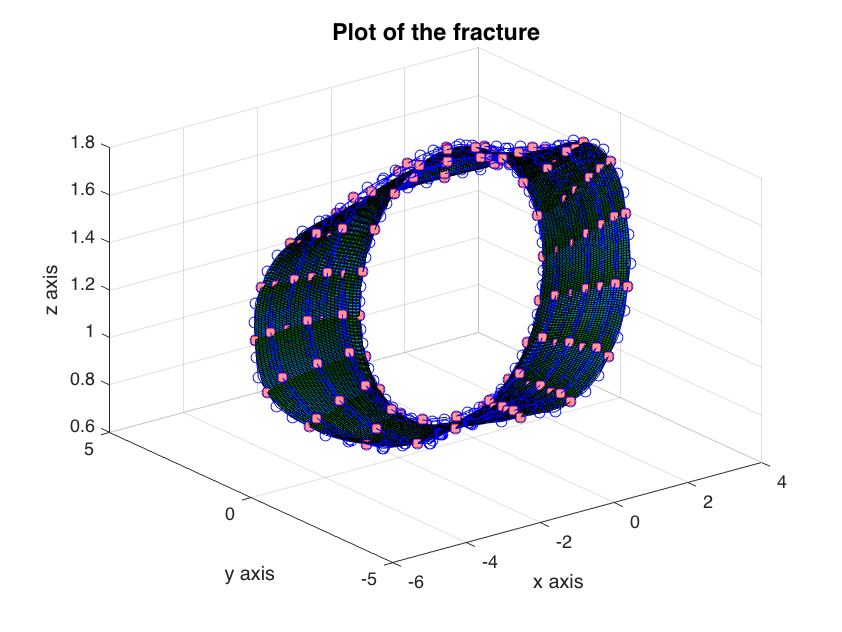

vector_parche_bezier_x = zeros(length(v),length(u));
vector_parche_bezier_y = zeros(length(v),length(u));
vector_parche_bezier_z = zeros(length(v),length(u));

numero_puntos_u = 4;
numero_puntos_v = 7; 

grado_u = numero_puntos_u - 1; 
grado_v = numero_puntos_v - 1; 

matriz_elipsoide_parches = zeros(7*4,3); 

% Desde donde se va a iniciar a ver los parches 
ni = 0;

% Hasta donde se van a ver los parches 
nf = (puntos - 1);
% nf = 0;

punto_a_evaluar = zeros(1,3);

for j = ni:nf
    for i = 1:numero_puntos_v
        Matriz_x(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),1,i);
        Matriz_y(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),2,i);
        Matriz_z(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),3,i);
    end
    
% Construcción de los parches de bezier   
    for k1 = 1:length(v)
        for k = 1:length(u)
            for i = 0:grado_u 
                Polinomio_Bernstien_u(i+1,:) = nchoosek(grado_u,i)*(1-u(k)).^(grado_u - i).* u(k).^i;
            end 
            for i = 0:grado_v 
                Polinomio_Bernstien_v(i+1,:) = nchoosek(grado_v,i)*(1-v(k1)).^(grado_v - i).* v(k1).^i;
            end 
            
            transpuesto_polinomio_Bernstein_v = transpose(Polinomio_Bernstien_v);
            
            multiplicacion_x = Matriz_x * Polinomio_Bernstien_u;
            multiplicacion_y = Matriz_y * Polinomio_Bernstien_u;
            multiplicacion_z = Matriz_z * Polinomio_Bernstien_u;
    
            premultiplicacion_x = multiplicacion_x(:,1);
            premultiplicacion_y = multiplicacion_y(:,1);
            premultiplicacion_z = multiplicacion_z(:,1);
    
            post_multiplicacion_x = transpuesto_polinomio_Bernstein_v(1,:) * premultiplicacion_x;
            post_multiplicacion_y = transpuesto_polinomio_Bernstein_v(1,:) * premultiplicacion_y;
            post_multiplicacion_z = transpuesto_polinomio_Bernstein_v(1,:) * premultiplicacion_z;
            
            vector_parche_bezier_x(k1,k) = post_multiplicacion_x;
            vector_parche_bezier_y(k1,k) = post_multiplicacion_y;
            vector_parche_bezier_z(k1,k) = post_multiplicacion_z; 
    
        end
            vector_parche_bezier_x;
            vector_parche_bezier_y;
            vector_parche_bezier_z;
            
 % Se pintan los parches con la matriz color, la cual indica la cantida de roj, verde y azul que se va a utilizar           
            color(:,:,1) = zeros(30); % rojo 
            color(:,:,2) = ones(30).*linspace(0.5,0.6,30); % verde 
            color(:,:,3) = ones(30).*linspace(0,1,30); % azul 
    end
    

    hold on 
    surf(vector_parche_bezier_x,vector_parche_bezier_y,vector_parche_bezier_z,color,'DisplayName','Parche de Bézier')

end

Minimizar el volumen de los elipsoides 

punto_medio_origen =    -0.0006   -0.0025   -0.0002


matriz_rotacion =     0.1389    0.9889    0.0526
    0.9844   -0.1320   -0.1164
   -0.1082    0.0680   -0.9918


determinanate_matriz_rotacion = 1.0000

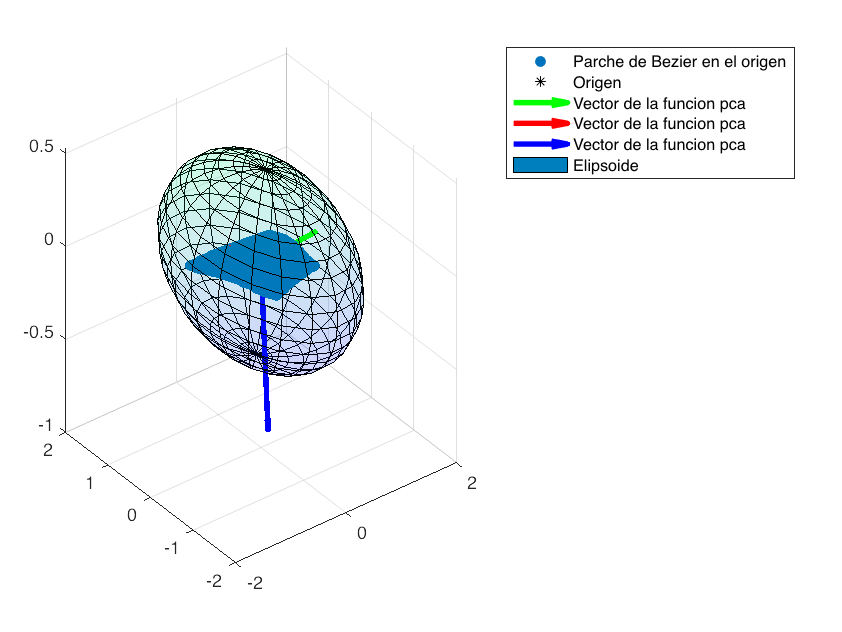


i1 =[1,0,0];
j1 = [0,1,0];
producto_punto_ejemplo = dot(i1,j1);

vector_parche_bezier_x = zeros(length(v),length(u));
vector_parche_bezier_y = zeros(length(v),length(u));
vector_parche_bezier_z = zeros(length(v),length(u));

numero_puntos_u = 4;
numero_puntos_v = 7; 

grado_u = numero_puntos_u - 1; 
grado_v = numero_puntos_v - 1; 

matriz_elipsoide_parches = zeros(7*4,3); 

% Parametros que van a reducir el volumen del elipsoide
n1 = 1; 
n2 = 1;
n3 = 1;

% Desde donde se va a iniciar a ver los parches 
ni = 0;

% Hasta donde se van a ver los parches 
% nf = (puntos - 1);
nf = 0;

% Vectores para la minimización del volumen de elipsoide
indice_punto_a_evaluer1 = [1 1 1 1];
indice_punto_a_evaluer2 = [1 1 1 1];

punto_a_evaluar = zeros(1,3);

% Tolerancia 
tol = 0.01; 

% Cambio de los ejes 
delta = 0.01;

for j = ni:nf
    for i = 1:numero_puntos_v
        Matriz_x(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),1,i);
        Matriz_y(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),2,i);
        Matriz_z(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),3,i);
    end
    
% Construcción de los parches de bezier   
    for k1 = 1:length(v)
        for k = 1:length(u)
            for i = 0:grado_u 
                Polinomio_Bernstien_u(i+1,:) = nchoosek(grado_u,i)*(1-u(k)).^(grado_u - i).* u(k).^i;
            end 
            for i = 0:grado_v 
                Polinomio_Bernstien_v(i+1,:) = nchoosek(grado_v,i)*(1-v(k1)).^(grado_v - i).* v(k1).^i;
            end 
            
            transpuesto_polinomio_Bernstein_v = transpose(Polinomio_Bernstien_v);
            
            multiplicacion_x = Matriz_x * Polinomio_Bernstien_u;
            multiplicacion_y = Matriz_y * Polinomio_Bernstien_u;
            multiplicacion_z = Matriz_z * Polinomio_Bernstien_u;
    
            premultiplicacion_x = multiplicacion_x(:,1);
            premultiplicacion_y = multiplicacion_y(:,1);
            premultiplicacion_z = multiplicacion_z(:,1);
    
            post_multiplicacion_x = transpuesto_polinomio_Bernstein_v(1,:) * premultiplicacion_x;
            post_multiplicacion_y = transpuesto_polinomio_Bernstein_v(1,:) * premultiplicacion_y;
            post_multiplicacion_z = transpuesto_polinomio_Bernstein_v(1,:) * premultiplicacion_z;
            
            vector_parche_bezier_x(k1,k) = post_multiplicacion_x;
            vector_parche_bezier_y(k1,k) = post_multiplicacion_y;
            vector_parche_bezier_z(k1,k) = post_multiplicacion_z; 
    
        end
            vector_parche_bezier_x;
            vector_parche_bezier_y;
            vector_parche_bezier_z;
            
 % Se pintan los parches con la matriz color, la cual indica la cantida de roj, verde y azul que se va a utilizar           
            color(:,:,1) = zeros(30); % rojo 
            color(:,:,2) = ones(30).*linspace(0.5,0.6,30); % verde 
            color(:,:,3) = ones(30).*linspace(0,1,30); % azul 
    end

% Dibujo los puntos del parche
    for i = 1:7 
%         hold on 
%         plot3(Matriz_x(i,:),Matriz_y(i,:),Matriz_z(i,:),'--sb','MarkerEdgeColor','b','MarkerFaceColor',[1 .6 .6],'DisplayName','Puntos del parche')
    end 
    
% Dibujo el parche de Bezier 
%     hold on 
%     surf(vector_parche_bezier_x,vector_parche_bezier_y,vector_parche_bezier_z,color,'DisplayName', 'Parche')
puntos_parche_x = vector_parche_bezier_x(:);
puntos_parche_y = vector_parche_bezier_y(:);
puntos_parche_z = vector_parche_bezier_z(:);

%     scatter3(puntos_parche_x,puntos_parche_y,puntos_parche_z,'filled','DisplayName', 'Parche en forma de puntos')
 
 % Realizar la SVD para cada uno de los parches de bezier 
 
 % Construcción de la matriz para realizar SVD y la construccion del elipsoide 
    for i = 0:6
    matriz_elipsoide_parches((1+4*i):(4*(1+i)),1) = Matriz_x(1+i,1:4);
    matriz_elipsoide_parches((1+4*i):(4*(1+i)),2) = Matriz_y(1+i,1:4);
    matriz_elipsoide_parches((1+4*i):(4*(1+i)),3) = Matriz_z(1+i,1:4);
    end   
    
    size(matriz_elipsoide_parches);
     
% SVD para los parches 
[Up,Sp,Vp] = svd(matriz_elipsoide_parches);
punto_medio_parche = mean(matriz_elipsoide_parches);

% Ver las matrices creadas por SVD
Up; % matriz 28x28
Sp; % matriz 28x3
Vp; % matriz 3x3 


% vector_fila_svd1 = [Vp(1,1) Vp(1,2) Vp(1,3)];
% vector_fila_svd2 = [Vp(2,1) Vp(2,2) Vp(2,3)];
% vector_fila_svd3 = [Vp(3,1) Vp(3,2) Vp(3,3)];
% 
% % Vectores de las filas de la matriz Vp 
% hold on 
% quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),vector_fila_svd1(1),vector_fila_svd1(2),vector_fila_svd1(3),'r','DisplayName','Vectores fila')
% quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),vector_fila_svd2(1),vector_fila_svd2(2),vector_fila_svd2(3),'r','DisplayName','Vectores fila')
% quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),vector_fila_svd3(1),vector_fila_svd3(2),vector_fila_svd3(3),'r','DisplayName','Vectores fila')


vector_columna_svd1 = [Vp(1,1) Vp(2,1) Vp(3,1)];
vector_columna_svd2 = [Vp(1,2) Vp(2,2) Vp(3,2)];
% vector_columna_svd3 = [Vp(1,3) Vp(2,3) Vp(3,3)];
% Vectores de las columnas de la matriz Vp 

% hold on 
% q1svd = quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),vector_columna_svd1(1),vector_columna_svd1(2),vector_columna_svd1(3),'g','DisplayName','Vectores columna');
% q2svd = quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),vector_columna_svd2 (1),vector_columna_svd2 (2),vector_columna_svd2 (3),'r','DisplayName','Vectores columna');
% q3svd = quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),vector_columna_svd3(1),vector_columna_svd3(2),vector_columna_svd3(3),'g','DisplayName','Vectores columna')
% q1svd.LineWidth = 2;
% q2svd.LineWidth = 2;
% legend 

% Verificar la  ortogoalidad de los vectores
% producto_punto_v1_v2 = dot(vector_columna_svd1,vector_columna_svd2)
% producto_punto_v2_v3 = dot(vector_columna_svd2,vector_columna_svd3)
% producto_punto_v1_v3 = dot(vector_columna_svd1,vector_columna_svd3)

% Otro metedo para encontrar los vactores utilizando pca
xpca = puntos_parche_x;
ypca = puntos_parche_y;
zpca = puntos_parche_z;

Upca = pca([xpca,ypca,zpca]);
%Despliegue de los vectores encontrados por la funcion pca
% hold on
% q1pca = quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),Upca(1,2),Upca(2,2),Upca(3,2),'g','DisplayName','Vector de la funcion pca');
% q2pca = quiver3(punto_medio_parche(1),punto_medio_parche(2),punto_medio_parche(3),Upca(1,1),Upca(2,1),Upca(3,1),'r','DisplayName','Vector de la funcion pca');
% q1pca.LineWidth = 3;
% q2pca.LineWidth = 3;
% legend


% Plano de los vectores columna de la SVD
vector1c = [vector_columna_svd1(1)-punto_medio_parche(1) vector_columna_svd1(2)-punto_medio_parche(2) vector_columna_svd1(3)-punto_medio_parche(3)];
vector2c = [vector_columna_svd2(1)-punto_medio_parche(1) vector_columna_svd2(2)-punto_medio_parche(2) vector_columna_svd2(3)-punto_medio_parche(3)];

[gamma,beta] = meshgrid(-0.2:0.1:0.2,-0.2:0.1:0.2);

xplano = punto_medio_parche(1) + gamma.*vector1c(1) + beta.*vector2c(1);
yplano = punto_medio_parche(2) + gamma.*vector1c(2) + beta.*vector2c(2);
zplano = punto_medio_parche(3) + gamma.*vector1c(3) + beta.*vector2c(3);

% Dibujar el plano 
% hold on 
% surf(xplano,yplano,zplano,'DisplayName','Plano de las columnas de SVD')

%Calcular la nueva posición del parche, llevarlo al origen 
origen_puntoX = puntos_parche_x - punto_medio_parche(1);
origen_puntoY = puntos_parche_y - punto_medio_parche(2);
origen_puntoZ = puntos_parche_z - punto_medio_parche(3);

matriz_origen(:,1) = origen_puntoX;
matriz_origen(:,2) = origen_puntoY;
matriz_origen(:,3) = origen_puntoZ;

punto_medio_origen = mean(matriz_origen)

figure
scatter3(origen_puntoX,origen_puntoY,origen_puntoZ,'filled','DisplayName','Parche de Bezier en el origen')
hold on 
%Dibujar el origen 
plot3(0, 0, 0, '*k', 'DisplayName','Origen')

xpca_origen = origen_puntoX;
ypca_origen = origen_puntoY;
zpca_origen = origen_puntoZ;

Upca_origen = pca([xpca_origen,ypca_origen,zpca_origen]);
%Despliegue de los vectores encontrados por la funcion pca
hold on
q1pca_origen = quiver3(punto_medio_origen(1),punto_medio_origen(2),punto_medio_origen(3),Upca_origen(1,2),Upca_origen(2,2),Upca_origen(3,2),'g','DisplayName','Vector de la funcion pca');
q2pca_origen = quiver3(punto_medio_origen(1),punto_medio_origen(2),punto_medio_origen(3),Upca_origen(1,1),Upca_origen(2,1),Upca_origen(3,1),'r','DisplayName','Vector de la funcion pca');
q1pca_origen.LineWidth = 3;
q2pca_origen.LineWidth = 3;
legend

% Encontrar el vector ortonormal a los vectores del fitting 
fitting1 = [Upca_origen(1,1),Upca_origen(2,1),Upca_origen(3,1)];
fitting2 = [Upca_origen(1,2),Upca_origen(2,2),Upca_origen(3,2)];
fitting3 = cross(fitting1,fitting2);

hold on 
q3pca_origen = quiver3(punto_medio_origen(1),punto_medio_origen(2),punto_medio_origen(3),fitting3(1),fitting3(2),fitting3(3),'b','DisplayName','Vector de la funcion pca');
q3pca_origen.LineWidth = 3;

% Se va a generar la matriz para rotar los puntos del elipsoide para que
% coincidan 
matriz_rotacion = [fitting1' fitting2' fitting3']

% Verificación de que la matriz es una rotación. Si el determinante da 1 es
% una rotación si da -1 es una rotación con una reflexión. 
determinanate_matriz_rotacion = det(matriz_rotacion)


% Minimizar el volumen del elipsoide
% Ejes del elipsoide
a = 1.5;
b = 1.5; 
c = 0.5; 

% Creación del elipsoide, por medio de la funcion ellipsoid()
colormap winter
[Xp,Yp,Zp] = ellipsoid(punto_medio_origen(1), punto_medio_origen(2),punto_medio_origen(3), ...
   a,b,c);

% Rotación del elipsoide 
Xp1 = Xp(:);
Yp1 = Yp(:);
Zp1 = Zp(:);
matriz_elipsoide_origen = [Xp1 Yp1 Zp1];
max = length(matriz_elipsoide_origen);


for i = 1:max
    matriz_elipsoide_rotada(i,:) = matriz_elipsoide_origen(i,:) * matriz_rotacion;
end

Xp_rotada = [];
Yp_rotada = [];
Zp_rotada = [];

for i = 0:20
    for j = 1:21
        Xp_rotada(j,i+1) = matriz_elipsoide_rotada(j+(i*21),1);
        Yp_rotada(j,i+1) = matriz_elipsoide_rotada(j+(i*21),2);    
        Zp_rotada(j,i+1) = matriz_elipsoide_rotada(j+(i*21),3);
    end 
end 


hold on 
% Dibujar el elipsoide
surf(Xp_rotada,Yp_rotada,Zp_rotada,'FaceAlpha',0.1,'DisplayName','Elipsoide')

    
end

Apendice

% Evaluación del elipsoide
% for i = 1:4
% 
%     punto_a_evaluar = [Matriz_x(indice_punto_a_evaluer1(i),indice_punto_a_evaluer2(i)), Matriz_y(indice_punto_a_evaluer1(i),indice_punto_a_evaluer2(i)),Matriz_z(indice_punto_a_evaluer1(i),indice_punto_a_evaluer2(i))];
% 
% 
% % Funcion del elipsoide 
%  elipsoide = ((punto_a_evaluar(1)-punto_medio_parche(1))/a)^2 + ((punto_a_evaluar(2)-punto_medio_parche(2))/b)^2 + ((punto_a_evaluar(3)-punto_medio_parche(3))/c)^2;
% 
%     while elipsoide < 1 - tol 
%         
%         n1 = n1 + delta;
%         n2 = n2 + delta;
%         n3 = n3 + delta; 
%         
%         a = sqrt(Sp(1,1))/n1;
%         b = sqrt(Sp(2,2))/n2; 
%         c = sqrt(Sp(3,3))/n3; 
%         
%         elipsoide = ((punto_a_evaluar(1)-punto_medio_parche(1))/a)^2 + ((punto_a_evaluar(2)-punto_medio_parche(2))/b)^2 + ((punto_a_evaluar(3)-punto_medio_parche(3))/c)^2;
%     end
% end 